## Load the .mat file first

## The perfect channel (the original channel)

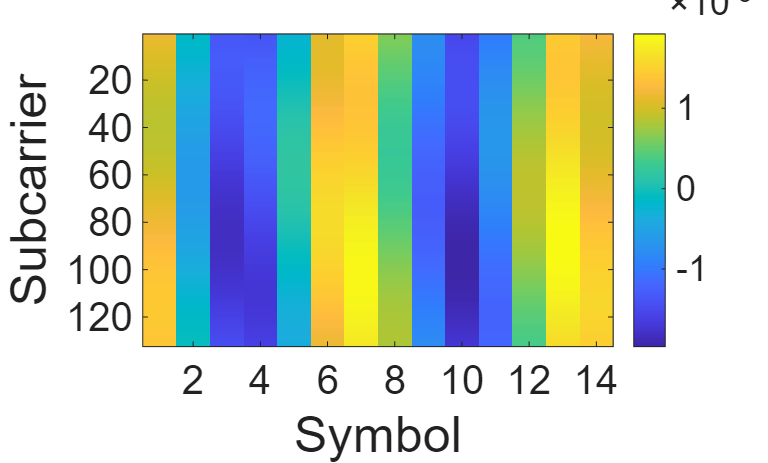

figure; 
imagesc(real(H_perfect_ori(:,:,900).')); 
colorbar;
set(gca, 'FontSize', 20);  % affects tick labels and axis numbers

% Optional: set font size for colorbar ticks and label
% cb = colorbar;
% cb.FontSize = 12;                   % font size of colorbar tick labels

xlabel('Symbol', 'FontSize', 25);
ylabel('Subcarrier', 'FontSize',25)

## The effective channel considering Doppler Precompensation

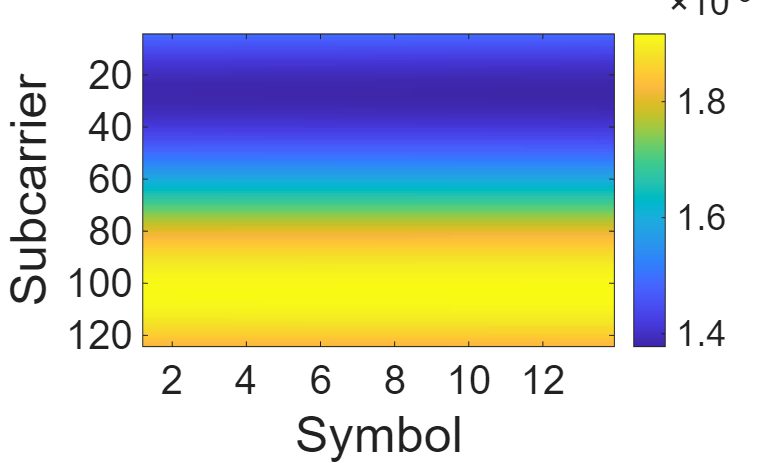

figure; 
imagesc(real(H_perfect(:,:,900).')); 
colorbar;
set(gca, 'FontSize', 20);  % affects tick labels and axis numbers

% Optional: set font size for colorbar ticks and label
% cb = colorbar;
% cb.FontSize = 12;                   % font size of colorbar tick labels

xlabel('Symbol', 'FontSize', 25);
ylabel('Subcarrier', 'FontSize',25)

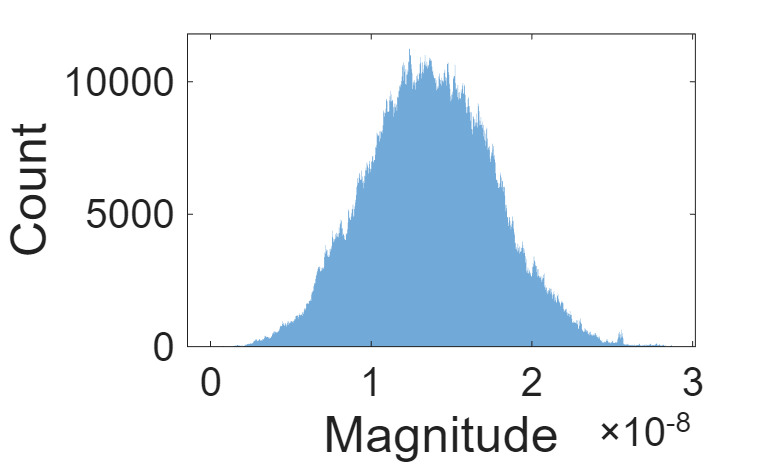

H_abs = abs(H_perfect);             % Take absolute values (magnitudes)
H_abs_all = H_abs(:);       % Convert to a single vector
figure;
h = histogram(H_abs_all, 1000, 'EdgeColor', 'none');  % Plot histogram with 100 bins
h.FaceColor = [0.07 0.44 0.75];
set(gca, 'FontSize', 20);  % affects tick labels and axis numbers
xlabel('Magnitude', 'FontSize',25);
ylabel('Count', 'FontSize',25);
ymax = max(h.Values);      % Get the height of the tallest bin
ylim([0, ymax * 1.05]);     % Set y-axis limit slightly higher (10% higher)

% title('Histogram of |H|');

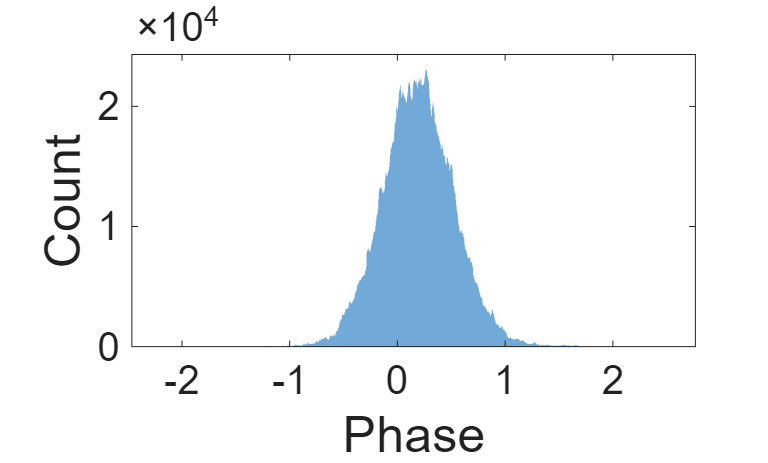

H_phase = angle(H_perfect);             % Take absolute values (magnitudes)
H_phase_all = H_phase(:);       % Convert to a single vector
figure;
h = histogram(H_phase_all, 1000, 'EdgeColor', 'none');  % Plot histogram with 100 bins
h.FaceColor = [0.07 0.44 0.75];
set(gca, 'FontSize', 20);  % affects tick labels and axis numbers
xlabel('Phase', 'FontSize',25);
ylabel('Count', 'FontSize',25);
ymax = max(h.Values);      % Get the height of the tallest bin
ylim([0, ymax * 1.05]);     % Set y-axis limit slightly higher (10% higher)

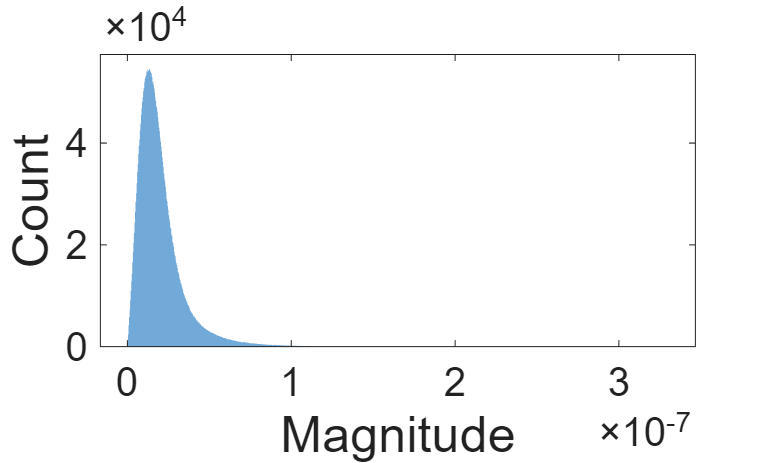

H_abs = abs(H_li);
H_abs_all = H_abs(:);       % Convert to a single vector
figure;
h = histogram(H_abs_all, 1000, 'EdgeColor', 'none');  % Plot histogram with 100 bins
h.FaceColor = [0.07 0.44 0.75];
set(gca, 'FontSize', 20);  % affects tick labels and axis numbers
xlabel('Magnitude', 'FontSize',25);
ylabel('Count', 'FontSize',25);
ymax = max(h.Values);      % Get the height of the tallest bin
ylim([0, ymax * 1.05]);     % Set y-axis limit slightly higher (10% higher)

## LI-, LS- estimated channels

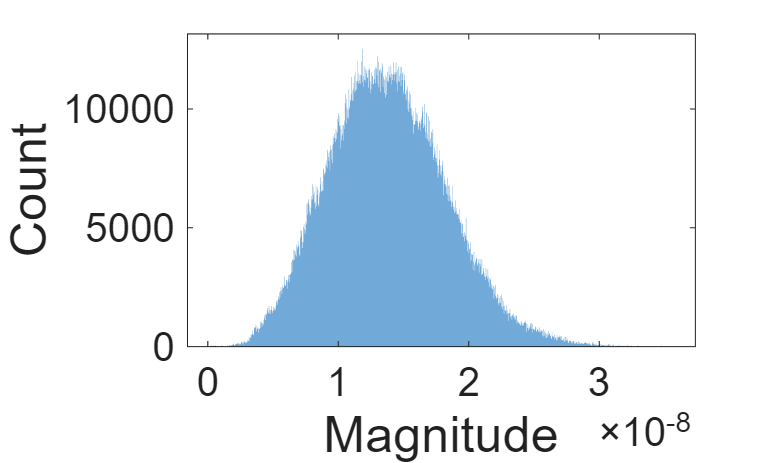

H_abs = abs(H_prac);
H_abs_all = H_abs(:);       % Convert to a single vector
figure;
h = histogram(H_abs_all, 1000, 'EdgeColor', 'none');  % Plot histogram with 100 bins
h.FaceColor = [0.07 0.44 0.75];
set(gca, 'FontSize', 20);  % affects tick labels and axis numbers
xlabel('Magnitude', 'FontSize',25);
ylabel('Count', 'FontSize',25);
ymax = max(h.Values);      % Get the height of the tallest bin
ylim([0, ymax * 1.05]);     % Set y-axis limit slightly higher (10% higher)

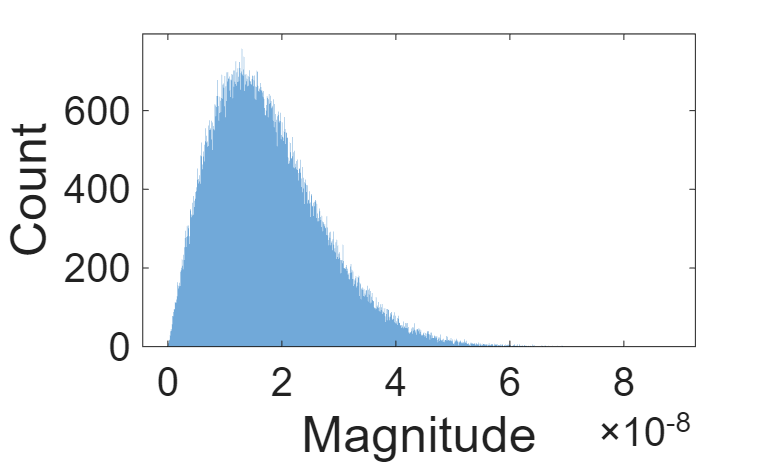

H_abs = abs(H_ls);
H_abs_all = H_abs(:);       % Convert to a single vector
H_abs_all_nonzero = H_abs_all(H_abs_all ~= 0);
figure;
h = histogram(H_abs_all_nonzero, 1000, 'EdgeColor', 'none');  % Plot histogram with 100 bins
h.FaceColor = [0.07 0.44 0.75];
set(gca, 'FontSize', 20);  % affects tick labels and axis numbers
xlabel('Magnitude', 'FontSize',25);
ylabel('Count', 'FontSize',25);
ymax = max(h.Values);      % Get the height of the tallest bin
ylim([0, ymax * 1.05]);     % Set y-axis limit slightly higher (10% higher)